# Game Analysis

clearvars

dataFileName = "C:\Users\pbergman\GIT25\ZDATA00\beamData001_20220627_044140.mat";
load(dataFileName);

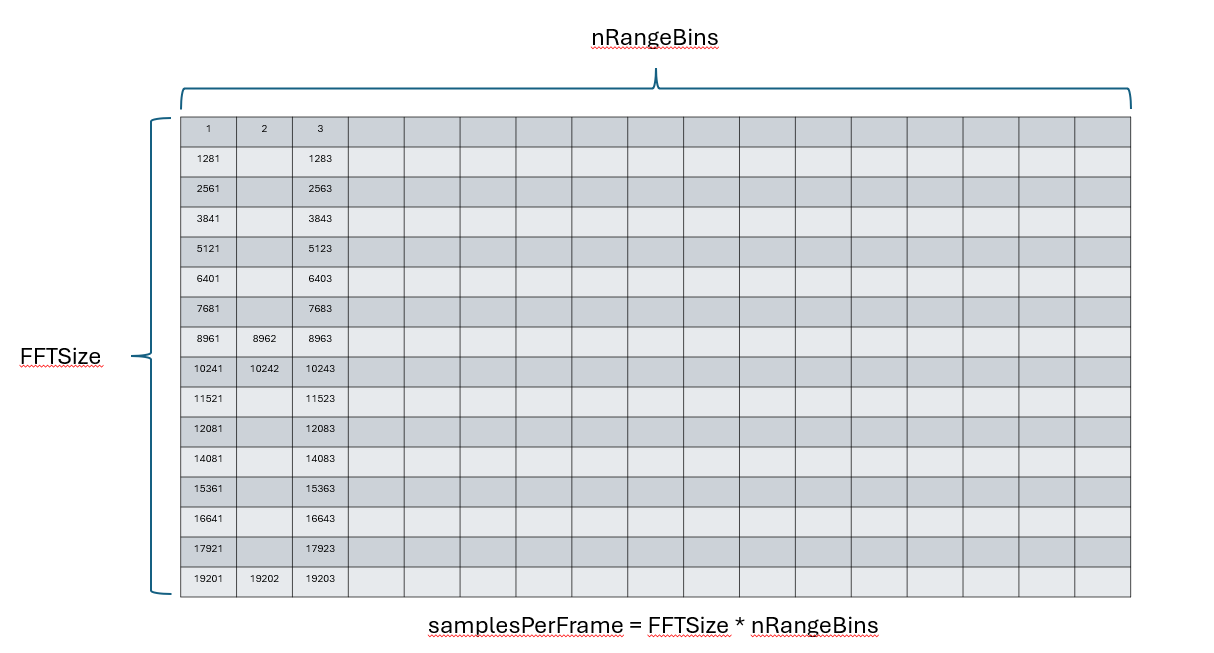

BREAK


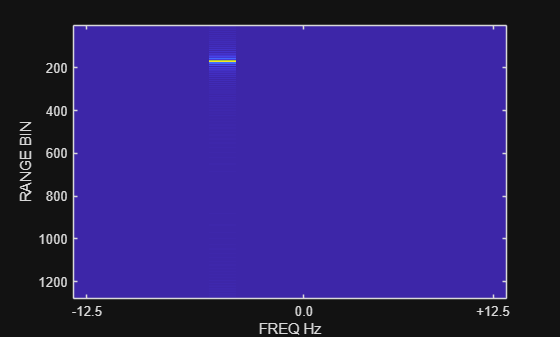

fftSize = 16;

nRangeBins = ROP.Tau*ROP.Fs;

samplesPerFrame = fftSize .* nRangeBins;

fftIndexes = generateFFTIndexes(fftSize, nRangeBins);

nTotalSamples = length(pulseCompressedBeam_);

nImages = fix( nTotalSamples./samplesPerFrame );

imageBuffer = zeros(nRangeBins, fftSize);

for ii = 1:nImages
  strt = (ii-1) * samplesPerFrame + 1;
  stop = ii*samplesPerFrame;
  buffer00 = pulseCompressedBeam_(strt:stop);

  for rngBin = 1:nRangeBins
    tmp00 = buffer00(fftIndexes + rngBin - 1);
    imageBuffer(rngBin,:) = fftshift( fft(tmp00) );
  end
 
  frame = abs(imageBuffer);
  frameMax = max(max(frame));
  image(255*frame./frameMax);
  xlabel("FREQ Hz");
  xticks([1 9 16])
  xticklabels({'-12.5', '0.0', '+12.5'})
  ylabel("RANGE BIN");
  drawnow;

  if ii == 150
    disp("BREAK");
  end

end

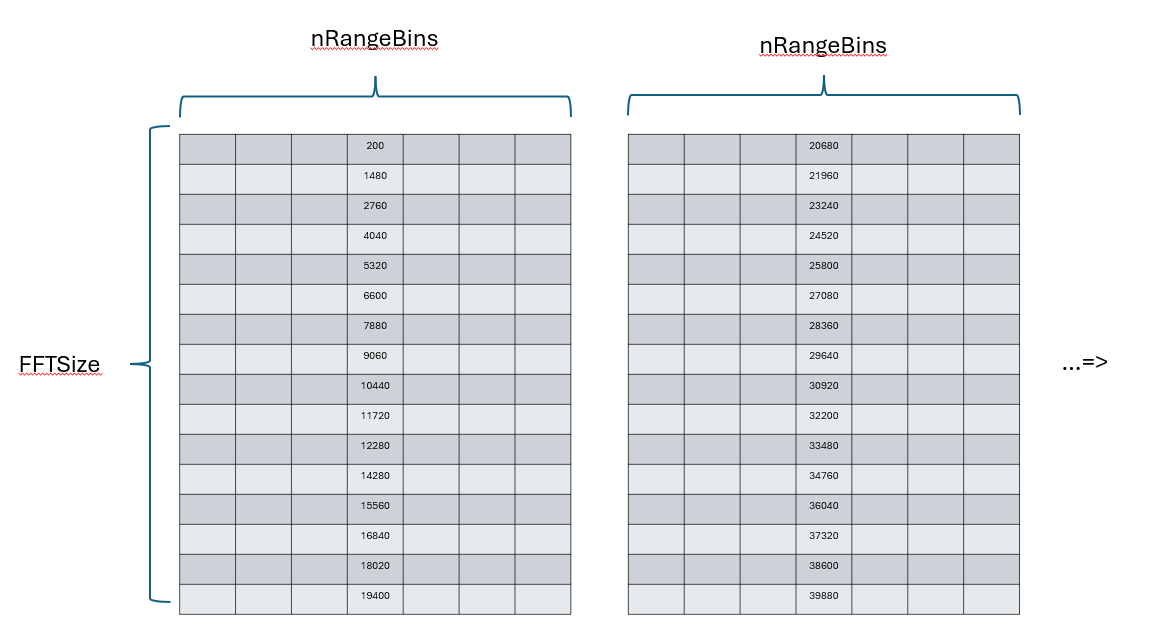

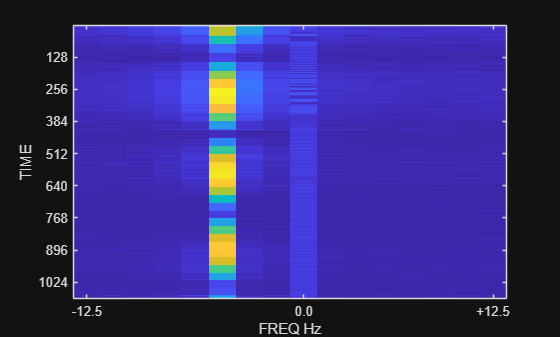

rangeBin = 55;
buff00Size = fix( nTotalSamples./nRangeBins );
buff00_ = zeros(buff00Size,1);
for ii = 1:buff00Size
  strt = rangeBin + (ii-1)*nRangeBins;
  buff00_(ii) = pulseCompressedBeam_(strt);
end

nFFT = fix( buff00Size./fftSize );
waterFallFFT = zeros(nFFT,fftSize);

for jj = 1:nFFT
  strt = (jj-1)*fftSize+1;
  stop = jj*fftSize;
  waterFallFFT(jj,:) = fftshift(fft( buff00_(strt:stop) ));
end

frame = abs(waterFallFFT);
frameMax = max(max(frame));
h2a = axes( figure() );
image(h2a,255*frame./frameMax);
xlabel("FREQ Hz");
ylabel("TIME");
xticks([1 9 16])
xticklabels({'-12.5', '0.0', '+12.5'})
yticklabels(yticks(h2a)*.04*16)

Function to help generate list of sample numbers to pull FFT from.

function fftDex = generateFFTIndexes(fftSize, nSamples)
%
%
  fftDex = zeros(fftSize,1);
  for ii = 1:fftSize
    fftDex(ii) =  (ii-1) * nSamples + 1;
  end
end